clearvars
clear
clc
%stock the audioData
wavFile = 'AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav'

wavFile = 'AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav'

[signal,Fs] = audioread(wavFile);
signal = signal(:,1) % signal = toutes les lignes de la première colonne

signal =     0.0003
    0.0008
    0.0014
    0.0019
    0.0025
    0.0032
    0.0042
    0.0052
    0.0066
    0.0080


%parametre

FFTSize = 2048;
hopsize = 250; %changer de nom overlapp, overlap = nombre de samples commun
overlapp = FFTSize -hopsize;

filterOrder = 3;
cutoff = 37;
cutoffRad = cutoff/Fs/2;

downSamplingFactor = 4;


N = length(signal)

N = 394222

time = [0:N-1]/Fs

time =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010



%le nombre de FFT a effectuer pour couvrir tout le signal
numberFFT  = floor((N-FFTSize)/hopsize);

audio = miraudio(wavFile,'Normal');

Computing miraudio related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Computing mirsum related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Elapsed time is 0.226023 seconds.


mirfilter = mirfilterbank(audio);

Computing mirfilterbank related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...


filterdata = mirgetdata(mirfilter);
filteredSignal = filterdata(:,:,7)

filteredSignal =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0001


filteredSignalfeedWithZero = zeros(FFTSize+length(filteredSignal),1)

filteredSignalfeedWithZero =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


filteredSignalfeedWithZero(FFTSize+1:end) = filteredSignal;
spectrogram (filteredSignalfeedWithZero,hanning(FFTSize),overlapp,FFTSize,Fs,'yaxis')
[s,f,t] = spectrogram (filteredSignalfeedWithZero,hanning(FFTSize),overlapp,FFTSize-1,Fs,'yaxis')

s =    0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i  -0.0002 + 0.0000i  -0.0005 + 0.0000i  -0.0003 + 0.0000i   0.0001 + 0.0000i   0.0006 + 0.0000i   0.0008 + 0.0000i   0.0005 + 0.0000i   0.0000 + 0.0000i  -0.0003 + 0.0000i  -0.0004 + 0.0000i  -0.0005 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0001 + 0.0000i  -0.0003 + 0.0000i  -0.0002 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0000 + 0.0000i   0.0001 + 0.0000i   0.0003 + 0.0000i   0.0005 + 0.0000i   0.0004 + 0.0000i   0.0002 + 0.0000i   0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i   0.0002 + 0.0000i   0.0003 + 0.0000i   0.0002 + 0.0000i  -0.0001 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0001 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i
   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.00

f = 	1.0e+04 *

         0
    0.0023
    0.0047
    0.0070
    0.0094
    0.0117
    0.0141
    0.0164
    0.0188
    0.0211


t =     0.0213    0.0265    0.0318    0.0370    0.0422    0.0474    0.0526    0.0578    0.0630    0.0682    0.0734    0.0786    0.0838    0.0890    0.0943    0.0995    0.1047    0.1099    0.1151    0.1203    0.1255    0.1307    0.1359    0.1411    0.1463    0.1515    0.1568    0.1620    0.1672    0.1724    0.1776    0.1828    0.1880    0.1932    0.1984    0.2036    0.2088    0.2140    0.2193    0.2245    0.2297    0.2349    0.2401    0.2453    0.2505    0.2557    0.2609    0.2661    0.2713    0.2765


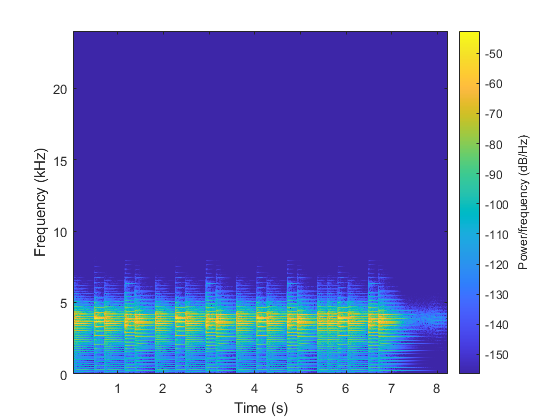

hold off;


power = zeros(size(s,2),1)

power =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for index =1:size(s,2)
    power(index) = 1/FFTSize * sum(abs(s(:,index)));
end
t  = t - (FFTSize-hopsize) * 1/Fs; 


filterOrder = 1;
cutoff = 1000;
cutoffRad = cutoff/Fs/2;
[b,a] = butter(filterOrder,cutoffRad);
sys = tf(b,a,1/Fs)

sys =
 
  0.0161 z + 0.0161
  -----------------
     z - 0.9678
 
Sample time: 2.0833e-05 seconds
Discrete-time transfer function.



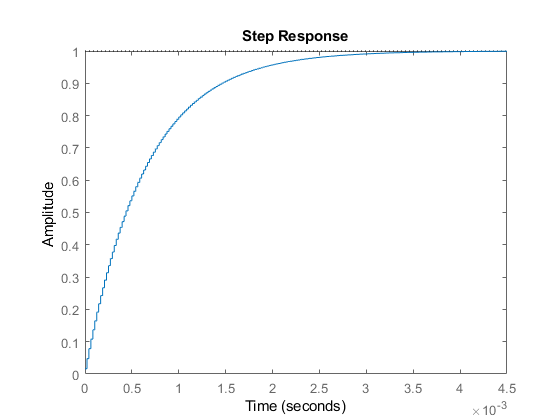

step(sys)

iir = dsp.IIRFilter('Numerator',b,'Denominator',a);
powerSmoothed = iir(power)

powerSmoothed =          0
    0.0000
    0.0002
    0.0006
    0.0015
    0.0028
    0.0042
    0.0055
    0.0066
    0.0076


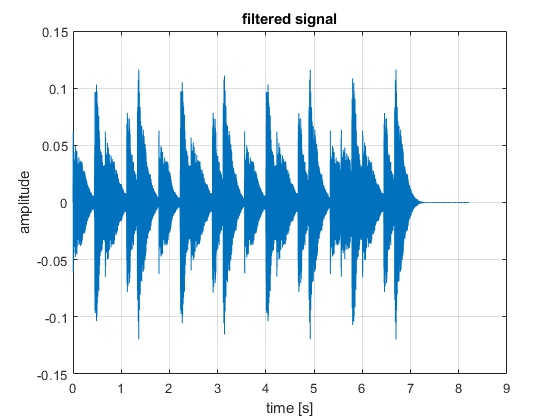

power = power(1:downSamplingFactor:end);
newtime = t(1:downSamplingFactor:end);
diffPower = power(2:end) - power (1:end-1);
maxOfDiff = max(diffPower);
diffPowerNormalized = diffPower/maxOfDiff;



plot(time,filteredSignal)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("filtered signal")

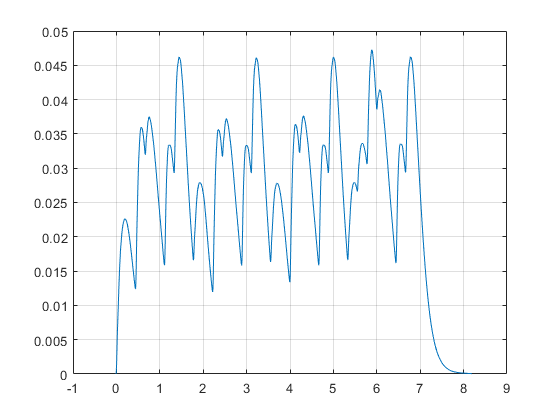


plot(t,powerSmoothed)
grid on

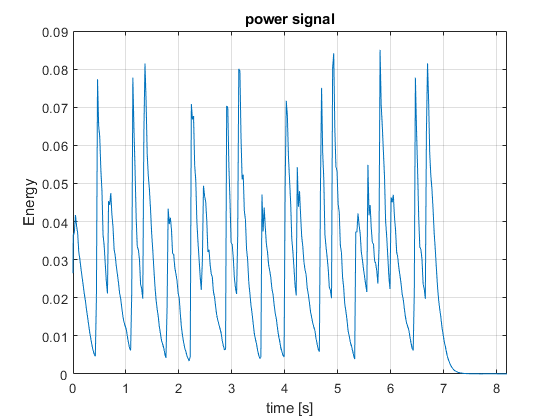


plot(newtime,power)
grid on
xlabel("time [s]")
ylabel("Energy")
title("power signal")
xlim([0 newtime(end)])

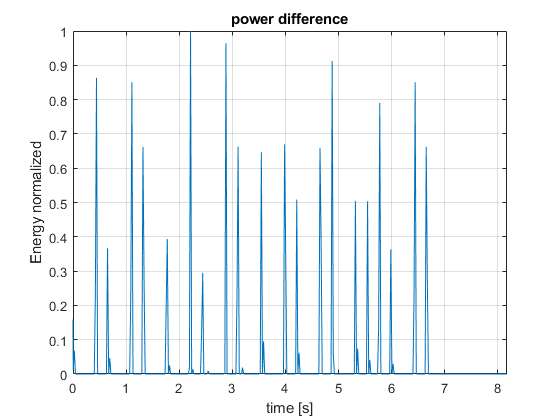



plot(newtime(1:end-1),max(diffPowerNormalized,0))
grid on
xlabel("time [s]")
ylabel("Energy normalized")
title("power difference")
xlim([0 newtime(end-1)])